# 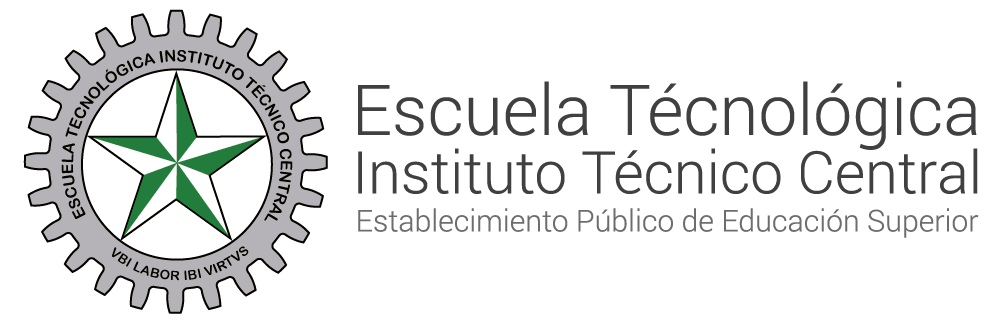

**SISTEMAS DE CONTROL II  **

# **Solución ecuaciones diferenciales **

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

**OBJETIVO** Comprender los sistemas de primer y segundo orden en el dominio del tiempo discreto.

En el contexto de sistemas lineales e invariantes en el tiempo (LTI), que son fundamentales en la teoría de control, un sistema de primer orden se define por su respuesta a un impulso unitario. La función de transferencia de un sistema de primer orden en el dominio de la frecuencia (para sistemas continuos) o en el dominio Z (para sistemas discretos) tiene la forma general:

Para sistemas discretos:


$$G\left(z\right)=\frac{b}{z-a}$$


*Donde a y b* son los coeficientes que definen el comportamiento del sistema

**Demostración **

Encuentre la función de transferencia para el siguiente sistema de primer orden dado en el dominio del tiempo discreto.


$$y\left\lbrack k+1\right\rbrack =a\;y\left\lbrack k\right\rbrack +b\;x\left\lbrack k\right\rbrack$$


Realizando la transformada Z del sistema obtenemso:


$$\left\lbrace y\left\lbrack k+1\right\rbrack =a\;y\left\lbrack k\right\rbrack +b\;x\left\lbrack k\right\rbrack \right\rbrace =\mathrm{zY}\left\lbrack z\right\rbrack =\mathrm{aY}\left\lbrack z\right\rbrack +\mathrm{bX}\left\lbrack x\right\rbrack$$


agrupando los terminos $Y\left\lbrack z\right\rbrack$ y despejando obtenemos


$$Y\left\lbrack z\right\rbrack \left(z-a\right)=b\;X\left\lbrack z\right\rbrack$$



$$Y\left\lbrack z\right\rbrack =X\left\lbrack x\right\rbrack \;\frac{b}{z-a}$$


Ahora despejamos X[z] con el objetivo de obtener la función de transferencia G(z)


$$G\left\lbrack z\right\rbrack =\frac{b}{z-a}$$


Donde 


$$a=e^{-\frac{T_s }{\mathrm{RC}}}$$


y 


$$b=\frac{{1-e}^{-\frac{T_s }{\mathrm{RC}}} }{\mathrm{RC}}$$


#### Ejercicio

Para el ejercicio de primer orden RC encuentre (Documento Sistemas_de_primer_orden_Continuo.mlx) la función de transferencia en z para Ts=1

Ts=1;
R=1;
C=1;
a=exp(-Ts/R*C)

a = 0.3679

b=(1-exp(-Ts/R*C))/R*C

b = 0.6321

syms z n;
G_z=b/(z-a)

$$G\_z = \frac{1423408956596761}{2251799813685248\,\left(z-\frac{828390857088487}{2251799813685248}\right)}$$

numerator = [b];
denominator = [1 -a];
Y_z = tf(numerator,denominator, Ts)


Y_z =
 
    0.6321
  ----------
  z - 0.3679
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


# Taller

- Para el ejercicio de primer orden RC encuentre (Documento Sistemas_de_primer_orden_Continuo.mlx) la función de transferencia en z para Ts=[0.1, 2, 10]

Encuentre la respuesta al escalón unitario

Expanda en fracciones parciales 

Encuentre la transformada Z inversa

Grafique a mano

Grafique en Matlab

Compare con las soluciones con el Documento "Sistemas_de_primer_orden_Continuo.mlx"

- Encuentre la función de transferencia en z,  encuentre la respuesta a la rampa  (Ts=1s en t discreto) ***(Ejercicio propuesto para Examen 1)***